omega = 2*pi*1e9;
t1 = out.tout(1);
t2 = out.tout(2);
A1 = out.voltage(1);
A2 = out.voltage(2);
B1 = out.current(1);
B2 = out.current(2);

temp = (A1*sin(omega*t2) - A2*sin(omega*t1))/...
    (A2*cos(omega*t1) - A1*cos(omega*t2));
tetaV = atan(temp);
tetaVD = tetaV*180/pi;
V = A1/sin(omega*t1 + tetaV);

tetaV = tetaV + pi;
tetaVD = tetaV*180/pi;
V = -V;

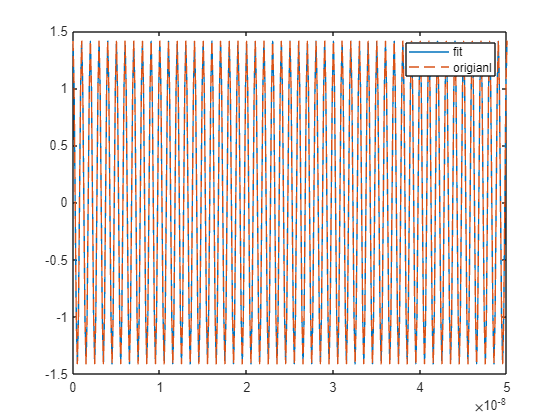

plot(out.tout, V*sin(omega*out.tout + tetaV))
hold on
plot(out.tout, out.voltage, LineStyle="--")
legend ('fit', 'origianl')
hold off

temp = (B1*sin(omega*t2) - B2*sin(omega*t1))/...
    (B2*cos(omega*t1) - B1*cos(omega*t2));
tetaI = atan(temp);
tetaID = tetaI*180/pi;
I = B1/sin(omega*t1 + tetaI);

% tetaI = tetaI + pi;
% tetaID = tetaI*180/pi;
% I = -I;

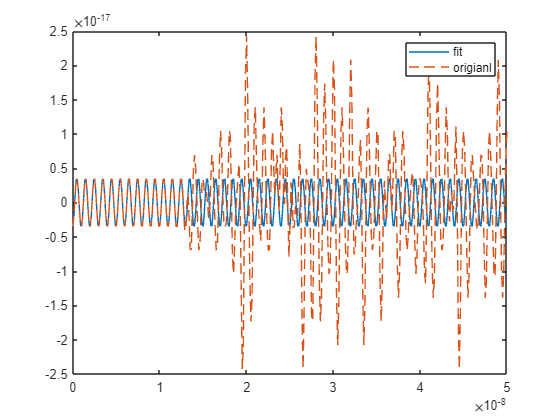

plot(out.tout, I*sin(omega*out.tout + tetaI))
hold on
plot(out.tout, out.current, LineStyle="--")
legend ('fit', 'origianl')
hold off

z = (V/I)*(cos(tetaV-tetaI)+1i*sin(tetaV-tetaI));
hz = zparameters(z, 1e9);
gama = (z-50)/(z+50);

% Z11 = rfparam(hz,1,1);
% Freq = hz.Frequencies;
% smithplot()
% s = smithplot('gco');
% add(s, Freq, Z11);